% AAE 532 HW 8 Problem 2
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps8';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
moon = planet_consts.moon;  % structure of moon
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% Set given constants
h_PO = 190;  % earth parking orbit altitude 
h_cap = 200;  % moon capture orbit altitude

% (a)
r_minus = earth.mer + h_PO

r_minus = 6.5681e+03

r_plus = moon.smao - h_cap - moon.mer 

r_plus = 3.8246e+05

a_T = 0.5*(r_minus+r_plus)

a_T = 1.9451e+05

e_T = (r_plus - r_minus) / (r_plus + r_minus)

e_T = 0.9662

p_T = a_T * (1 - e_T^2)

p_T = 1.2914e+04

IP_minus = 2*pi*sqrt(a_T^3 / earth.gp)

IP_minus = 8.5377e+05

IP_minus_days = IP_minus / 60 / 60 / 24

IP_minus_days = 9.8816

xi_minus = -earth.gp / 2 / a_T

xi_minus = -1.0246

v_PO = sqrt(earth.gp / r_minus)

v_PO = 7.7902

v_plus = vis_viva(r_minus, a_T, earth.gp)

v_plus = 10.9236

Dv_dep = v_plus - v_PO

Dv_dep = 3.1334

v_minus = vis_viva(r_plus, a_T, earth.gp)

v_minus = 0.1876

v_moon = sqrt(earth.gp / moon.smao)

v_moon = 1.0183

v_inf_moon = abs(v_minus - v_moon)

v_inf_moon = 0.8307

v_c_moon = sqrt(moon.gp / (moon.mer + h_cap))

v_c_moon = 1.5905

Dv_arr = sqrt( v_inf_moon^2 + 2*moon.gp / (moon.mer + 200) ) - v_c_moon

Dv_arr = 0.8073

Dv_total = Dv_dep + Dv_arr

Dv_total = 3.9407

TOF = IP_minus / 2 

TOF = 4.2688e+05

TOF_days = TOF / 60 / 60 / 24

TOF_days = 4.9408

phi = rad2deg(pi - sqrt(earth.gp / moon.smao^3)*TOF)

phi = 115.2072

% (b)

xi_plus = v_inf_moon^2 / 2

xi_plus = 0.3450

a_plus = -earth.gp / 2 / xi_plus

a_plus = -5.7762e+05

e_plus = 1 - (h_cap + moon.mer) / a_plus

e_plus = 1.0034

delta = 2*asind(1 / e_plus)

delta = 170.6257

v_plus = sqrt( v_inf_moon^2 + v_moon^2 - 2*v_inf_moon*v_moon*cosd(delta) )

v_plus = 1.8429

FPA_plus = asind( v_inf_moon / v_plus * sind(delta))

FPA_plus = 4.2106


% True anomaly
temp = r_plus * v_plus^2 / earth.gp;
TA_plus = atand( temp*sind(FPA_plus)*cosd(FPA_plus) / ( temp*cosd(FPA_plus)^2 - 1 ))

TA_plus = 6.0774

Domega = 180 - TA_plus

Domega = 173.9226

% characterisitics
a_N = -earth.gp / 2 / (v_plus^2 / 2 - earth.gp / r_plus)

a_N = -3.0384e+05

h_N = r_plus*v_plus*cosd(FPA_plus)

h_N = 7.0293e+05

p_N = h_N^2 / earth.gp

p_N = 1.2396e+06

e_N =  sqrt(1 - p_N / a_N)

e_N = 2.2538

r_aN = a_N * (1 + e_N)

r_aN = -9.8866e+05

r_pN = abs(a_N) * (e_N - 1)

r_pN = 3.8097e+05

xi_N = -earth.gp / 2 / a_N 

xi_N = 0.6559

IP_N = 2*pi * sqrt(a_N^3 / earth.gp)

IP_N = 0.0000e+00 + 1.6668e+06i

IP_N_year = IP_N / 60 /60 / 24 / 365

IP_N_year = 0.0000 + 0.0529i

% (c)
Dv_eq = 2 * v_inf_moon * sind(delta / 2)

Dv_eq = 1.6559

alpha = (180 - delta) / 2

alpha = 4.6872

Dv_eq_vec = Dv_eq * [cosd(alpha), sind(alpha), 0]

Dv_eq_vec =     1.6503    0.1353         0


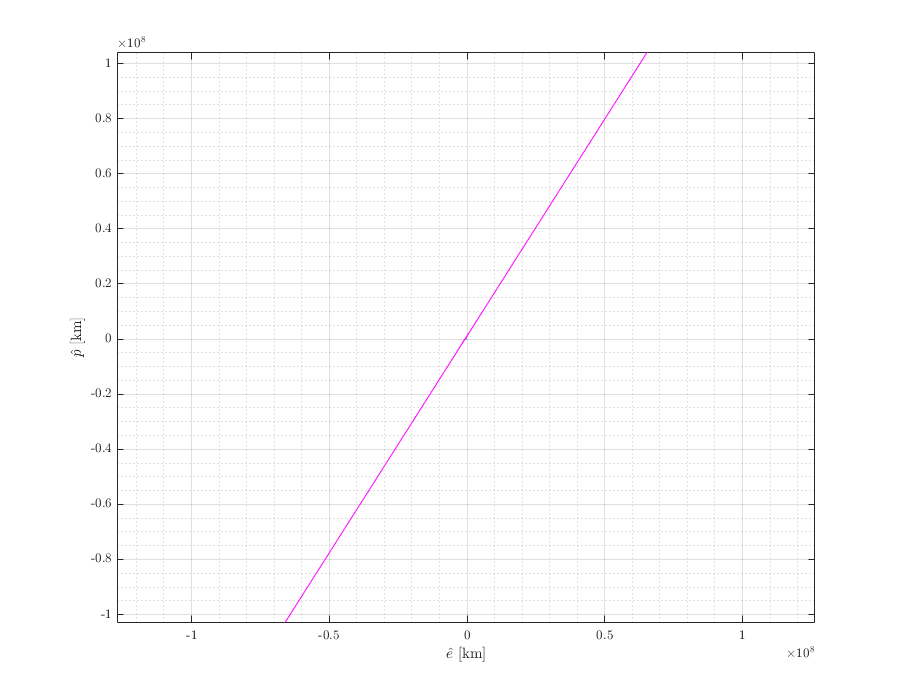

% Plotting for visualization 


% old orbit
angles = 0:0.01:pi;
RR = p_T ./ (1 + e_T*cos(angles)); XX = RR.*cos(angles); YY = RR.*sin(angles);

% new orbit
RR_new = p_N ./ (1 + e_N*cos(angles - deg2rad(Domega)));
XX_new = RR_new.*cos(angles);
YY_new = RR_new.*sin(angles);

new_angles = TA_plus:20;
Xsun = sun.mer*cos(new_angles); Ysun = sun.mer*sin(new_angles);
fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
    plot(XX,YY)
    hold on; grid on; grid minor; box on; axis equal; 
    plot(XX_new, YY_new, '-m')
    hold off
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')